# Design of Resonant Bandpass Filters

This live script is for use with the textbook

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach*

by O. Alkin, CRC Press, 2025.

Start with poles at $z=r e^{j\mp\Omega_{0}$ with $r=0.8$ and $\Omega_{0}=0.4\pi$:


$$H(z)=\frac{1}{\left(z-r e^{j\Omega_{0}}\right)\,\left(z-r e^{-j\Omega_{0}}\right)} = \frac{1}{z^{2}-2r\cos\left(\Omega_{0}\right)\,z+r^{2|}$$


For details, see Section 8.3.1 of the text.

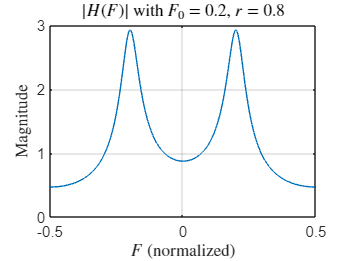

F = [-0.5:0.001:0.5];
Omega = 2*pi*F;
F0 = 0.2;       % Resonant normalized frequency
Omg0 = 2*pi*F0; % Resonant angular frequency
r = 0.8;        % Distance of poles from origin
zrs = [];       % Zeros
pls = [r*exp(j*Omg0),r*exp(-j*Omg0)]; % Poles
[mag,phs] = ss_freqz(zrs,pls,1,Omega);
plot(F,mag); grid;
set(0,'defaultTextInterpreter','latex');
xlabel('$F$ (normalized)');
ylabel('Magnitude');
title('$|H(F)|$ with $F_{0}=0.2$, $r=0.8$');

Move poles closer to the unit circle with $r=0.9$.  Observe how this causes the peaks to become sharper.

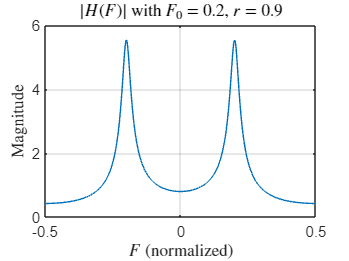

r = 0.9;
pls = [r*exp(j*Omg0),r*exp(-j*Omg0)];
[mag,phs] = ss_freqz(zrs,pls,1,Omega);
plot(F,mag); grid;
xlabel('$F$ (normalized)');
ylabel('Magnitude');
title('$|H(F)|$ with $F_{0}=0.2$, $r=0.9$');

Now add zeros at $\Omega=0$ and $\Omega=\mp\pi$.  These frequencies translate to the points $z=1$ and $z=-1$ on the unit circle of the $z$-plane.  The effect is to further pull the magnitude response down at frequencies away from the resonant peaks.  The system function becomes 


$$H(z)=\frac{K\,\left(z^{2}-1\right)}{z^{2}-2r\,\cos\left(\Omega_{0}\right)\,z+r^{2}}$$


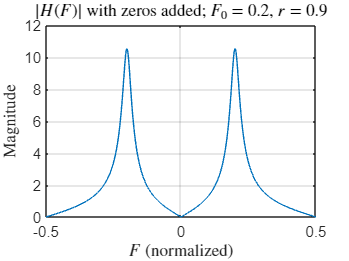

% Add two zeros at z=1 and z=-1
zrs = [-1,1];
[mag,phs] = ss_freqz(zrs,pls,1,Omega);
plot(F,mag); grid;
xlabel('$F$ (normalized)');
ylabel('Magnitude');
title('$|H(F)|$ with zeros added; $F_{0}=0.2$, $r=0.9$');

Adjust the gain factor $K$ so that the peak magnitude is unity.  See Eqn. (8.13) in the text.

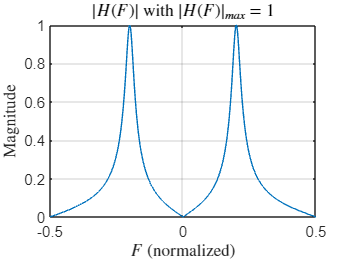

% Determine the gain factor so that the peak 
% magnitude is 1
peak = ss_freqz(zrs,pls,1,Omg0);
gain = 1/peak;
[mag,phs] = ss_freqz(zrs,pls,gain,Omega);
plot(F,mag); grid;
xlabel('$F$ (normalized)');
ylabel('Magnitude');
title('$|H(F)|$ with $|H(F)|_{max}=1$');

Adjust the $3$-dB bandwidth to $F_{b}=0.02$ normalized.  The pole radius needs to be chosen as


$$r=1-\frac{\Omega_{b}}{2}$$


See Fig. 8.7 and Eqns. (8.7) through (8.12) in the text.

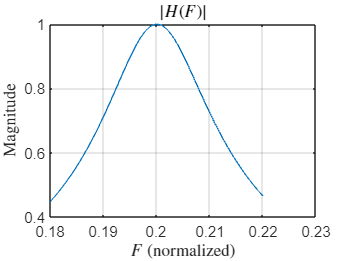

DF = 0.02;    % Normalized 3-dB bandwidth
r = 1-pi*DF;  % Compute pole radius
pls = [r*exp(j*Omg0),r*exp(-j*Omg0)]; % Poles
% Recompute F and Omg vectors to zoom in for the
% resonant frequency
F = [0.18:0.001:0.22];
Omega = 2*pi*F;
% Determine the gain factor so that the peak 
% magnitude is 1
peak = ss_freqz(zrs,pls,1,Omg0);
gain = 1/peak;
% Compute the frequency response
[mag,phs] = ss_freqz(zrs,pls,gain,Omega);
plot(F,mag); grid;
xlabel('$F$ (normalized)');
ylabel('Magnitude');
title('$|H(F)|$');

set(0,'defaultTextInterpreter','tex');